## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from PDE model with Reflecting boundaries |x|<=a.

This scrip just changing para by hand and make the frame of simulation.

## fv1 Intro

In this scrip, we try to adjust para automatically. First we use **gradient descent**. 

## fv4 Intro

In this scrip we try different input to get min residual.

## Import data and previewing

The data come from expomential fitness data.

data_name='p47';
selecting_curve='xy';
experiment_interval=5;
min_length=51;
time_scale=experiment_interval*(1:min_length);

fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
t=time_scale;
a(1)=1.046e+05;%p47_5s
a(2)=0.0004364;
a(3)=-7.307e+04;
a(4)=-0.03125;

Reserved_length=min_length;
interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Main loop

residual_min=1;
range_a=8e-7:2e-8:14e-7;
range_Gamma=0.44:0.01:0.56;
range_K_gamma=8e-15:0.5e-15:20e-15;
total_work=length(range_a)*length(range_Gamma)*length(range_K_gamma);
progress=0;
for a=range_a
    for Gamma=range_Gamma
        for K_gamma=range_K_gamma
            input=[a,Gamma,K_gamma];
            try
                [parameter_history,residual_history]=FDE_GD_SD(experiment_interval,Reserved_length,interceptive_experiment_MSD,input);
            catch
            end
            if residual_history(end)<residual_min
                best_para=parameter_history(end,:);
                residual_min=residual_history(end);
                disp([num2str(best_para),'\',num2str(residual_min)])
            end
            progress=progress+1;
            disp(['complete ',num2str(progress),'/',num2str(total_work)])
        end
    end
end

8.4698e-07     0.47656  8.2695e-15\2.6637e-25


complete 1/10075


8.4664e-07     0.47362  8.7632e-15\2.4567e-25


complete 2/10075


8.4614e-07     0.47097  9.2565e-15\2.2705e-25


complete 3/10075


8.4552e-07     0.46856  9.7493e-15\2.1028e-25


complete 4/10075


8.4482e-07     0.46638  1.0242e-14\1.9512e-25


complete 5/10075


8.4402e-07     0.46439  1.0734e-14\1.8141e-25


complete 6/10075


8.4318e-07     0.46258  1.1227e-14\1.6898e-25


complete 7/10075


8.4231e-07     0.46094  1.1719e-14\1.5769e-25


complete 8/10075


8.4142e-07     0.45944  1.2212e-14\1.4742e-25


complete 9/10075


8.4051e-07     0.45807  1.2704e-14\1.3805e-25


complete 10/10075


8.3961e-07     0.45682  1.3197e-14\1.2951e-25


complete 11/10075


8.3872e-07     0.45568   1.369e-14\1.217e-25


complete 12/10075


8.3785e-07     0.45464  1.4183e-14\1.1456e-25


complete 13/10075


8.37e-07     0.45369  1.4677e-14\1.0802e-25


complete 14/10075


8.3618e-07     0.45282   1.517e-14\1.0202e-25


complete 15/10075


8.354e-07     0.45202  1.5664e-14\9.6513e-26


complete 16/10075


8.3465e-07     0.45129  1.6159e-14\9.1454e-26


complete 17/10075


8.3394e-07     0.45062  1.6653e-14\8.6805e-26


complete 18/10075


8.3326e-07     0.45001  1.7148e-14\8.2526e-26


complete 19/10075


8.3263e-07     0.44945  1.7642e-14\7.8598e-26


complete 20/10075


8.3203e-07     0.44895  1.8138e-14\7.4983e-26


complete 21/10075


8.3191e-07     0.44824  1.8635e-14\7.1416e-26


complete 22/10075


8.3097e-07     0.44806  1.9129e-14\6.8564e-26


complete 23/10075


8.305e-07     0.44767  1.9625e-14\6.5715e-26


complete 24/10075


8.3007e-07     0.44731  2.0121e-14\6.3083e-26


complete 25/10075
complete 26/10075
complete 27/10075
complete 28/10075
complete 29/10075
complete 30/10075
complete 31/10075
complete 32/10075
complete 33/10075
complete 34/10075
complete 35/10075
complete 36/10075
complete 37/10075
complete 38/10075
complete 39/10075
complete 40/10075
complete 41/10075
complete 42/10075
complete 43/10075
complete 44/10075
complete 45/10075
complete 46/10075
complete 47/10075


8.294e-07     0.45746  1.9112e-14\6.2091e-26


complete 48/10075


8.2878e-07     0.45698  1.9607e-14\5.9535e-26


complete 49/10075


8.2865e-07     0.45678  2.0105e-14\5.7177e-26


complete 50/10075
complete 51/10075
complete 52/10075
complete 53/10075
complete 54/10075
complete 55/10075
complete 56/10075
complete 57/10075
complete 58/10075
complete 59/10075
complete 60/10075
complete 61/10075
complete 62/10075
complete 63/10075
complete 64/10075
complete 65/10075
complete 66/10075
complete 67/10075
complete 68/10075
complete 69/10075
complete 70/10075
complete 71/10075
complete 72/10075


8.2799e-07     0.46691  1.9098e-14\5.6191e-26


complete 73/10075


8.2767e-07     0.46659  1.9595e-14\5.3916e-26


complete 74/10075


8.2739e-07     0.46629  2.0091e-14\5.183e-26


complete 75/10075
complete 76/10075
complete 77/10075
complete 78/10075
complete 79/10075
complete 80/10075
complete 81/10075
complete 82/10075
complete 83/10075
complete 84/10075
complete 85/10075
complete 86/10075
complete 87/10075
complete 88/10075
complete 89/10075
complete 90/10075
complete 91/10075
complete 92/10075
complete 93/10075
complete 94/10075
complete 95/10075
complete 96/10075
complete 97/10075


8.266e-07     0.47631  1.9084e-14\5.1049e-26


complete 98/10075


8.265e-07     0.47611  1.9582e-14\4.8847e-26


complete 99/10075


8.2631e-07     0.47584  2.0079e-14\4.7016e-26


complete 100/10075
complete 101/10075
complete 102/10075
complete 103/10075
complete 104/10075
complete 105/10075
complete 106/10075
complete 107/10075
complete 108/10075
complete 109/10075
complete 110/10075
complete 111/10075
complete 112/10075
complete 113/10075
complete 114/10075
complete 115/10075
complete 116/10075
complete 117/10075
complete 118/10075
complete 119/10075
complete 120/10075
complete 121/10075
complete 122/10075


8.2566e-07     0.48593  1.9073e-14\4.606e-26


complete 123/10075


8.2551e-07     0.48566  1.9571e-14\4.4306e-26


complete 124/10075


8.2541e-07     0.48542  2.0068e-14\4.2713e-26


complete 125/10075
complete 126/10075
complete 127/10075
complete 128/10075
complete 129/10075
complete 130/10075
complete 131/10075
complete 132/10075
complete 133/10075
complete 134/10075
complete 135/10075
complete 136/10075
complete 137/10075
complete 138/10075
complete 139/10075
complete 140/10075
complete 141/10075
complete 142/10075
complete 143/10075
complete 144/10075
complete 145/10075
complete 146/10075
complete 147/10075


8.2468e-07     0.49545  1.9063e-14\4.1868e-26


complete 148/10075


8.2472e-07     0.49526  1.9561e-14\4.0263e-26


complete 149/10075


8.2474e-07     0.49505  2.0059e-14\3.8902e-26


complete 150/10075
complete 151/10075
complete 152/10075
complete 153/10075
complete 154/10075
complete 155/10075
complete 156/10075
complete 157/10075
complete 158/10075
complete 159/10075
complete 160/10075
complete 161/10075
complete 162/10075
complete 163/10075
complete 164/10075
complete 165/10075
complete 166/10075
complete 167/10075
complete 168/10075
complete 169/10075
complete 170/10075
complete 171/10075
complete 172/10075


8.2408e-07      0.5051  1.9054e-14\3.7981e-26


complete 173/10075


8.2416e-07     0.50489  1.9552e-14\3.6698e-26


complete 174/10075


8.243e-07      0.5047   2.005e-14\3.5553e-26


complete 175/10075
complete 176/10075
complete 177/10075
complete 178/10075
complete 179/10075
complete 180/10075
complete 181/10075
complete 182/10075
complete 183/10075
complete 184/10075
complete 185/10075
complete 186/10075
complete 187/10075
complete 188/10075
complete 189/10075
complete 190/10075
complete 191/10075
complete 192/10075
complete 193/10075
complete 194/10075
complete 195/10075
complete 196/10075
complete 197/10075


8.2363e-07     0.51474  1.9046e-14\3.4652e-26


complete 198/10075


8.2385e-07     0.51455  1.9544e-14\3.3586e-26


complete 199/10075


8.2416e-07     0.51438  2.0041e-14\3.2647e-26


complete 200/10075
complete 201/10075
complete 202/10075
complete 203/10075
complete 204/10075
complete 205/10075
complete 206/10075
complete 207/10075
complete 208/10075
complete 209/10075
complete 210/10075
complete 211/10075
complete 212/10075
complete 213/10075
complete 214/10075
complete 215/10075
complete 216/10075
complete 217/10075
complete 218/10075
complete 219/10075
complete 220/10075
complete 221/10075
complete 222/10075


8.2346e-07     0.52441  1.9038e-14\3.1765e-26


complete 223/10075


8.2386e-07     0.52424  1.9536e-14\3.0904e-26


complete 224/10075


8.2436e-07     0.52409  2.0033e-14\3.0159e-26


complete 225/10075
complete 226/10075
complete 227/10075
complete 228/10075
complete 229/10075
complete 230/10075
complete 231/10075
complete 232/10075
complete 233/10075
complete 234/10075
complete 235/10075
complete 236/10075
complete 237/10075
complete 238/10075
complete 239/10075
complete 240/10075
complete 241/10075
complete 242/10075
complete 243/10075
complete 244/10075
complete 245/10075
complete 246/10075


8.2313e-07     0.53426  1.8533e-14\3.0079e-26


complete 247/10075


8.2363e-07     0.53409   1.903e-14\2.9296e-26


complete 248/10075


8.2426e-07     0.53394  1.9528e-14\2.8629e-26


complete 249/10075


8.2503e-07     0.53379  2.0025e-14\2.807e-26


complete 250/10075
complete 251/10075
complete 252/10075
complete 253/10075
complete 254/10075
complete 255/10075
complete 256/10075
complete 257/10075
complete 258/10075
complete 259/10075
complete 260/10075
complete 261/10075
complete 262/10075
complete 263/10075
complete 264/10075
complete 265/10075
complete 266/10075
complete 267/10075
complete 268/10075
complete 269/10075
complete 270/10075
complete 271/10075


8.2348e-07     0.54395  1.8526e-14\2.7814e-26


complete 272/10075


8.2425e-07     0.54379  1.9023e-14\2.7225e-26


complete 273/10075


8.252e-07     0.54363  1.9519e-14\2.6744e-26


complete 274/10075


8.2636e-07     0.54346  2.0014e-14\2.6362e-26


complete 275/10075
complete 276/10075
complete 277/10075
complete 278/10075
complete 279/10075
complete 280/10075
complete 281/10075
complete 282/10075
complete 283/10075
complete 284/10075
complete 285/10075
complete 286/10075
complete 287/10075
complete 288/10075
complete 289/10075
complete 290/10075
complete 291/10075
complete 292/10075
complete 293/10075
complete 294/10075
complete 295/10075
complete 296/10075


8.2434e-07     0.55362  1.8518e-14\2.5936e-26


complete 297/10075


8.2549e-07     0.55344  1.9013e-14\2.5534e-26


complete 298/10075


8.2691e-07     0.55324  1.9508e-14\2.524e-26


complete 299/10075


8.287e-07       0.553       2e-14\2.5029e-26


complete 300/10075
complete 301/10075
complete 302/10075
complete 303/10075
complete 304/10075
complete 305/10075
complete 306/10075
complete 307/10075
complete 308/10075
complete 309/10075
complete 310/10075
complete 311/10075
complete 312/10075
complete 313/10075
complete 314/10075
complete 315/10075
complete 316/10075
complete 317/10075
complete 318/10075
complete 319/10075
complete 320/10075


8.2453e-07     0.56344  1.8013e-14\2.4756e-26


complete 321/10075


8.2593e-07     0.56323  1.8508e-14\2.4433e-26


complete 322/10075


8.277e-07     0.56297     1.9e-14\2.4217e-26


complete 323/10075


8.2996e-07     0.56261   1.949e-14\2.4099e-26


complete 324/10075


8.3293e-07     0.56204  1.9974e-14\2.4083e-26


complete 325/10075
complete 326/10075
complete 327/10075
complete 328/10075
complete 329/10075
complete 330/10075
complete 331/10075
complete 332/10075
complete 333/10075
complete 334/10075
complete 335/10075
complete 336/10075
complete 337/10075
complete 338/10075
complete 339/10075
complete 340/10075
complete 341/10075
complete 342/10075
complete 343/10075
complete 344/10075
complete 345/10075
complete 346/10075
complete 347/10075
complete 348/10075
complete 349/10075
complete 350/10075
complete 351/10075
complete 352/10075
complete 353/10075
complete 354/10075
complete 355/10075
complete 356/10075
complete 357/10075
complete 358/10075
complete 359/10075
complete 360/10075
complete 361/10075
complete 362/10075
complete 363/10075
complete 364/10075
complete 365/10075
complete 366/10075
complete 367/10075
complete 368/10075
complete 369/10075
complete 370/10075
complete 371/10075
complete 372/10075
complete 373/10075
complete 374/10075
complete 375/10075
complete 376/10075
complete 377

8.4206e-07     0.51418  1.9035e-14\2.3759e-26


complete 523/10075


8.4288e-07     0.51404  1.9532e-14\2.3039e-26


complete 524/10075


8.4396e-07     0.51391  2.0027e-14\2.2449e-26


complete 525/10075
complete 526/10075
complete 527/10075
complete 528/10075
complete 529/10075
complete 530/10075
complete 531/10075
complete 532/10075
complete 533/10075
complete 534/10075
complete 535/10075
complete 536/10075
complete 537/10075
complete 538/10075
complete 539/10075
complete 540/10075
complete 541/10075
complete 542/10075
complete 543/10075
complete 544/10075
complete 545/10075
complete 546/10075


8.4196e-07     0.52404  1.8529e-14\2.2225e-26


complete 547/10075


8.4301e-07     0.52389  1.9025e-14\2.1603e-26


complete 548/10075


8.4441e-07     0.52374   1.952e-14\2.1113e-26


complete 549/10075


8.4627e-07     0.52357  2.0012e-14\2.0751e-26


complete 550/10075
complete 551/10075
complete 552/10075
complete 553/10075
complete 554/10075
complete 555/10075
complete 556/10075
complete 557/10075
complete 558/10075
complete 559/10075
complete 560/10075
complete 561/10075
complete 562/10075
complete 563/10075
complete 564/10075
complete 565/10075
complete 566/10075
complete 567/10075
complete 568/10075
complete 569/10075
complete 570/10075
complete 571/10075


8.4333e-07     0.53372  1.8519e-14\2.0305e-26


complete 572/10075


8.4514e-07     0.53353  1.9012e-14\1.9918e-26


complete 573/10075


8.4764e-07     0.53326  1.9501e-14\1.9665e-26


complete 574/10075


8.5124e-07     0.53274   1.998e-14\1.9547e-26


complete 575/10075
complete 576/10075
complete 577/10075
complete 578/10075
complete 579/10075
complete 580/10075
complete 581/10075
complete 582/10075
complete 583/10075
complete 584/10075
complete 585/10075
complete 586/10075
complete 587/10075
complete 588/10075
complete 589/10075
complete 590/10075
complete 591/10075
complete 592/10075
complete 593/10075
complete 594/10075
complete 595/10075


8.4386e-07     0.54352  1.8012e-14\1.9136e-26


complete 596/10075


8.4625e-07     0.54325  1.8502e-14\1.8855e-26


complete 597/10075


8.4971e-07     0.54273  1.8984e-14\1.8721e-26


complete 598/10075
complete 599/10075
complete 600/10075
complete 601/10075
complete 602/10075
complete 603/10075
complete 604/10075
complete 605/10075
complete 606/10075
complete 607/10075
complete 608/10075
complete 609/10075
complete 610/10075
complete 611/10075
complete 612/10075
complete 613/10075
complete 614/10075
complete 615/10075
complete 616/10075
complete 617/10075
complete 618/10075


8.4246e-07     0.55353  1.7013e-14\1.8414e-26


complete 619/10075


8.4466e-07     0.55326  1.7505e-14\1.8088e-26


complete 620/10075


8.4787e-07     0.55279   1.799e-14\1.7919e-26


complete 621/10075


8.5281e-07     0.55164  1.8457e-14\1.7918e-26


complete 622/10075
complete 623/10075
complete 624/10075
complete 625/10075
complete 626/10075
complete 627/10075
complete 628/10075
complete 629/10075
complete 630/10075
complete 631/10075
complete 632/10075
complete 633/10075
complete 634/10075
complete 635/10075
complete 636/10075
complete 637/10075
complete 638/10075
complete 639/10075
complete 640/10075
complete 641/10075


8.4099e-07     0.56356  1.6014e-14\1.7767e-26


complete 642/10075


8.4296e-07     0.56331  1.6507e-14\1.7375e-26


complete 643/10075


8.4582e-07     0.56289  1.6995e-14\1.7153e-26


complete 644/10075


8.5022e-07     0.56197  1.7471e-14\1.7106e-26


complete 645/10075
complete 646/10075
complete 647/10075
complete 648/10075
complete 649/10075
complete 650/10075
complete 651/10075
complete 652/10075
complete 653/10075
complete 654/10075
complete 655/10075
complete 656/10075
complete 657/10075
complete 658/10075
complete 659/10075
complete 660/10075
complete 661/10075
complete 662/10075
complete 663/10075
complete 664/10075
complete 665/10075
complete 666/10075
complete 667/10075
complete 668/10075
complete 669/10075
complete 670/10075
complete 671/10075
complete 672/10075
complete 673/10075
complete 674/10075
complete 675/10075
complete 676/10075
complete 677/10075
complete 678/10075
complete 679/10075
complete 680/10075
complete 681/10075
complete 682/10075
complete 683/10075
complete 684/10075
complete 685/10075
complete 686/10075
complete 687/10075
complete 688/10075
complete 689/10075
complete 690/10075
complete 691/10075
complete 692/10075
complete 693/10075
complete 694/10075
complete 695/10075
complete 696/10075
complete 697

8.6344e-07     0.50386  1.9521e-14\1.7097e-26


complete 824/10075


8.661e-07     0.50371   2.001e-14\1.672e-26


complete 825/10075
complete 826/10075
complete 827/10075
complete 828/10075
complete 829/10075
complete 830/10075
complete 831/10075
complete 832/10075
complete 833/10075
complete 834/10075
complete 835/10075
complete 836/10075
complete 837/10075
complete 838/10075
complete 839/10075
complete 840/10075
complete 841/10075
complete 842/10075
complete 843/10075
complete 844/10075
complete 845/10075
complete 846/10075


8.6208e-07     0.51388  1.8523e-14\1.6307e-26


complete 847/10075


8.6462e-07     0.51371  1.9013e-14\1.5899e-26


complete 848/10075


8.6868e-07      0.5133  1.9491e-14\1.567e-26


complete 849/10075


8.7577e-07     0.51159  1.9925e-14\1.5646e-26


complete 850/10075
complete 851/10075
complete 852/10075
complete 853/10075
complete 854/10075
complete 855/10075
complete 856/10075
complete 857/10075
complete 858/10075
complete 859/10075
complete 860/10075
complete 861/10075
complete 862/10075
complete 863/10075
complete 864/10075
complete 865/10075
complete 866/10075
complete 867/10075
complete 868/10075
complete 869/10075


8.6066e-07     0.52384  1.7522e-14\1.5582e-26


complete 870/10075


8.6301e-07     0.52365  1.8013e-14\1.5118e-26


complete 871/10075


8.6671e-07     0.52331  1.8496e-14\1.4856e-26


complete 872/10075


8.7329e-07     0.52187  1.8944e-14\1.4802e-26


complete 873/10075
complete 874/10075
complete 875/10075
complete 876/10075
complete 877/10075
complete 878/10075
complete 879/10075
complete 880/10075
complete 881/10075
complete 882/10075
complete 883/10075
complete 884/10075
complete 885/10075
complete 886/10075
complete 887/10075
complete 888/10075
complete 889/10075
complete 890/10075
complete 891/10075
complete 892/10075
complete 893/10075


8.6121e-07     0.53366  1.7015e-14\1.4417e-26


complete 894/10075


8.6447e-07     0.53336  1.7502e-14\1.4089e-26


complete 895/10075


8.7023e-07     0.53229  1.7965e-14\1.3982e-26


complete 896/10075
complete 897/10075
complete 898/10075
complete 899/10075
complete 900/10075
complete 901/10075
complete 902/10075
complete 903/10075
complete 904/10075
complete 905/10075
complete 906/10075
complete 907/10075
complete 908/10075
complete 909/10075
complete 910/10075
complete 911/10075
complete 912/10075
complete 913/10075
complete 914/10075
complete 915/10075
complete 916/10075


8.5939e-07     0.54366  1.6016e-14\1.3799e-26


complete 917/10075


8.6212e-07     0.54341  1.6507e-14\1.3385e-26


complete 918/10075


8.6688e-07      0.5427  1.6983e-14\1.3199e-26


complete 919/10075
complete 920/10075
complete 921/10075
complete 922/10075
complete 923/10075
complete 924/10075
complete 925/10075
complete 926/10075
complete 927/10075
complete 928/10075
complete 929/10075
complete 930/10075
complete 931/10075
complete 932/10075
complete 933/10075
complete 934/10075
complete 935/10075
complete 936/10075
complete 937/10075
complete 938/10075
complete 939/10075
complete 940/10075


8.598e-07     0.55346  1.5511e-14\1.2766e-26


complete 941/10075


8.6354e-07     0.55301  1.5996e-14\1.2477e-26


complete 942/10075


8.7058e-07     0.55095  1.6444e-14\1.2453e-26


complete 943/10075
complete 944/10075
complete 945/10075
complete 946/10075
complete 947/10075
complete 948/10075
complete 949/10075
complete 950/10075
complete 951/10075
complete 952/10075
complete 953/10075
complete 954/10075
complete 955/10075
complete 956/10075
complete 957/10075
complete 958/10075
complete 959/10075
complete 960/10075
complete 961/10075
complete 962/10075
complete 963/10075


8.5763e-07     0.56351  1.4514e-14\1.2266e-26


complete 964/10075


8.6045e-07     0.56321  1.5005e-14\1.1841e-26


complete 965/10075


8.657e-07     0.56222  1.5479e-14\1.1685e-26


complete 966/10075
complete 967/10075
complete 968/10075
complete 969/10075
complete 970/10075
complete 971/10075
complete 972/10075
complete 973/10075
complete 974/10075
complete 975/10075
complete 976/10075
complete 977/10075
complete 978/10075
complete 979/10075
complete 980/10075
complete 981/10075
complete 982/10075
complete 983/10075
complete 984/10075
complete 985/10075
complete 986/10075
complete 987/10075
complete 988/10075
complete 989/10075
complete 990/10075
complete 991/10075
complete 992/10075
complete 993/10075
complete 994/10075
complete 995/10075
complete 996/10075
complete 997/10075
complete 998/10075
complete 999/10075
complete 1000/10075
complete 1001/10075
complete 1002/10075
complete 1003/10075
complete 1004/10075
complete 1005/10075
complete 1006/10075
complete 1007/10075
complete 1008/10075
complete 1009/10075
complete 1010/10075
complete 1011/10075
complete 1012/10075
complete 1013/10075
complete 1014/10075
complete 1015/10075
complete 1016/10075
complete 1017/

8.829e-07     0.51362  1.7507e-14\1.1315e-26


complete 1170/10075


8.9083e-07     0.51202  1.7944e-14\1.1186e-26


complete 1171/10075
complete 1172/10075
complete 1173/10075
complete 1174/10075
complete 1175/10075
complete 1176/10075
complete 1177/10075
complete 1178/10075
complete 1179/10075
complete 1180/10075
complete 1181/10075
complete 1182/10075
complete 1183/10075
complete 1184/10075
complete 1185/10075
complete 1186/10075
complete 1187/10075
complete 1188/10075
complete 1189/10075
complete 1190/10075
complete 1191/10075


8.7721e-07     0.52377  1.6022e-14\1.1168e-26


complete 1192/10075


8.8015e-07     0.52363  1.6512e-14\1.0649e-26


complete 1193/10075


8.863e-07     0.52284  1.6979e-14\1.0415e-26


complete 1194/10075
complete 1195/10075
complete 1196/10075
complete 1197/10075
complete 1198/10075
complete 1199/10075
complete 1200/10075
complete 1201/10075
complete 1202/10075
complete 1203/10075
complete 1204/10075
complete 1205/10075
complete 1206/10075
complete 1207/10075
complete 1208/10075
complete 1209/10075
complete 1210/10075
complete 1211/10075
complete 1212/10075
complete 1213/10075
complete 1214/10075
complete 1215/10075


8.776e-07     0.53358  1.5516e-14\1.009e-26


complete 1216/10075


8.8198e-07     0.53325  1.5999e-14\9.7219e-27


complete 1217/10075


8.9105e-07     0.52922  1.6396e-14\9.7024e-27


complete 1218/10075
complete 1219/10075
complete 1220/10075
complete 1221/10075
complete 1222/10075
complete 1223/10075
complete 1224/10075
complete 1225/10075
complete 1226/10075
complete 1227/10075
complete 1228/10075
complete 1229/10075
complete 1230/10075
complete 1231/10075
complete 1232/10075
complete 1233/10075
complete 1234/10075
complete 1235/10075
complete 1236/10075
complete 1237/10075
complete 1238/10075


8.753e-07     0.54358  1.4518e-14\9.68e-27


complete 1239/10075


8.7829e-07     0.54339  1.5009e-14\9.1415e-27


complete 1240/10075


8.8518e-07     0.54216  1.5471e-14\8.9414e-27


complete 1241/10075
complete 1242/10075
complete 1243/10075
complete 1244/10075
complete 1245/10075
complete 1246/10075
complete 1247/10075
complete 1248/10075
complete 1249/10075
complete 1250/10075
complete 1251/10075
complete 1252/10075
complete 1253/10075
complete 1254/10075
complete 1255/10075
complete 1256/10075
complete 1257/10075
complete 1258/10075
complete 1259/10075
complete 1260/10075
complete 1261/10075
complete 1262/10075


8.7532e-07     0.55342  1.4014e-14\8.7201e-27


complete 1263/10075


8.7955e-07       0.553  1.4499e-14\8.3068e-27


complete 1264/10075


8.8819e-07     0.54828  1.4904e-14\8.3013e-27


complete 1265/10075
complete 1266/10075
complete 1267/10075
complete 1268/10075
complete 1269/10075
complete 1270/10075
complete 1271/10075
complete 1272/10075
complete 1273/10075
complete 1274/10075
complete 1275/10075
complete 1276/10075
complete 1277/10075
complete 1278/10075
complete 1279/10075
complete 1280/10075
complete 1281/10075
complete 1282/10075
complete 1283/10075
complete 1284/10075
complete 1285/10075
complete 1286/10075


8.7546e-07     0.56323   1.351e-14\7.8644e-27


complete 1287/10075


8.813e-07     0.56229  1.3985e-14\7.6053e-27


complete 1288/10075
complete 1289/10075
complete 1290/10075
complete 1291/10075
complete 1292/10075
complete 1293/10075
complete 1294/10075
complete 1295/10075
complete 1296/10075
complete 1297/10075
complete 1298/10075
complete 1299/10075
complete 1300/10075
complete 1301/10075
complete 1302/10075
complete 1303/10075
complete 1304/10075
complete 1305/10075
complete 1306/10075
complete 1307/10075
complete 1308/10075
complete 1309/10075
complete 1310/10075
complete 1311/10075
complete 1312/10075
complete 1313/10075
complete 1314/10075
complete 1315/10075
complete 1316/10075
complete 1317/10075
complete 1318/10075
complete 1319/10075
complete 1320/10075
complete 1321/10075
complete 1322/10075
complete 1323/10075
complete 1324/10075
complete 1325/10075
complete 1326/10075
complete 1327/10075
complete 1328/10075
complete 1329/10075
complete 1330/10075
complete 1331/10075
complete 1332/10075
complete 1333/10075
complete 1334/10075
complete 1335/10075
complete 1336/10075
complete 1337/10075


8.9497e-07      0.5235  1.5019e-14\7.4798e-27


complete 1515/10075


9.0047e-07     0.52319  1.5497e-14\7.0781e-27


complete 1516/10075
complete 1517/10075
complete 1518/10075
complete 1519/10075
complete 1520/10075
complete 1521/10075
complete 1522/10075
complete 1523/10075
complete 1524/10075
complete 1525/10075
complete 1526/10075
complete 1527/10075
complete 1528/10075
complete 1529/10075
complete 1530/10075
complete 1531/10075
complete 1532/10075
complete 1533/10075
complete 1534/10075
complete 1535/10075
complete 1536/10075
complete 1537/10075
complete 1538/10075


8.956e-07     0.53332  1.4512e-14\6.5809e-27


complete 1539/10075


9.0484e-07     0.53095  1.4944e-14\6.3814e-27


complete 1540/10075
complete 1541/10075
complete 1542/10075
complete 1543/10075
complete 1544/10075
complete 1545/10075
complete 1546/10075
complete 1547/10075
complete 1548/10075
complete 1549/10075
complete 1550/10075
complete 1551/10075
complete 1552/10075
complete 1553/10075
complete 1554/10075
complete 1555/10075
complete 1556/10075
complete 1557/10075
complete 1558/10075
complete 1559/10075
complete 1560/10075
complete 1561/10075


8.9231e-07     0.54327  1.3516e-14\6.3112e-27


complete 1562/10075


8.9685e-07     0.54304  1.4002e-14\5.8114e-27


complete 1563/10075


9.0217e-07       0.536  1.4375e-14\5.7993e-27


complete 1564/10075


9.0983e-07      0.5282  1.4713e-14\5.7164e-27


complete 1565/10075
complete 1566/10075
complete 1567/10075
complete 1568/10075
complete 1569/10075
complete 1570/10075
complete 1571/10075
complete 1572/10075
complete 1573/10075
complete 1574/10075
complete 1575/10075
complete 1576/10075
complete 1577/10075
complete 1578/10075
complete 1579/10075
complete 1580/10075
complete 1581/10075
complete 1582/10075
complete 1583/10075
complete 1584/10075
complete 1585/10075


8.9221e-07     0.55311  1.3013e-14\5.5049e-27


complete 1586/10075


8.9916e-07     0.55216  1.3484e-14\5.157e-27


complete 1587/10075


9.0552e-07     0.54295  1.3829e-14\5.1486e-27


complete 1588/10075
complete 1589/10075
complete 1590/10075
complete 1591/10075
complete 1592/10075
complete 1593/10075
complete 1594/10075
complete 1595/10075
complete 1596/10075
complete 1597/10075
complete 1598/10075
complete 1599/10075
complete 1600/10075
complete 1601/10075
complete 1602/10075
complete 1603/10075
complete 1604/10075
complete 1605/10075
complete 1606/10075
complete 1607/10075
complete 1608/10075
complete 1609/10075


8.9219e-07     0.56293  1.2509e-14\4.7994e-27


complete 1610/10075


9.011e-07     0.55925  1.2942e-14\4.6052e-27


complete 1611/10075
complete 1612/10075
complete 1613/10075
complete 1614/10075
complete 1615/10075
complete 1616/10075
complete 1617/10075
complete 1618/10075
complete 1619/10075
complete 1620/10075
complete 1621/10075
complete 1622/10075
complete 1623/10075
complete 1624/10075
complete 1625/10075
complete 1626/10075
complete 1627/10075
complete 1628/10075
complete 1629/10075
complete 1630/10075
complete 1631/10075
complete 1632/10075
complete 1633/10075
complete 1634/10075
complete 1635/10075
complete 1636/10075
complete 1637/10075
complete 1638/10075
complete 1639/10075
complete 1640/10075
complete 1641/10075
complete 1642/10075
complete 1643/10075
complete 1644/10075
complete 1645/10075
complete 1646/10075
complete 1647/10075
complete 1648/10075
complete 1649/10075
complete 1650/10075
complete 1651/10075
complete 1652/10075
complete 1653/10075
complete 1654/10075
complete 1655/10075
complete 1656/10075
complete 1657/10075
complete 1658/10075
complete 1659/10075
complete 1660/10075


9.196e-07     0.52241   1.448e-14\4.5226e-27


complete 1839/10075
complete 1840/10075


9.2951e-07     0.50525  1.5112e-14\4.4934e-27


complete 1841/10075
complete 1842/10075
complete 1843/10075
complete 1844/10075
complete 1845/10075
complete 1846/10075
complete 1847/10075
complete 1848/10075
complete 1849/10075
complete 1850/10075
complete 1851/10075
complete 1852/10075
complete 1853/10075
complete 1854/10075
complete 1855/10075
complete 1856/10075
complete 1857/10075
complete 1858/10075
complete 1859/10075
complete 1860/10075
complete 1861/10075


9.1196e-07     0.53304  1.3512e-14\4.1449e-27


complete 1862/10075


9.1922e-07     0.52773  1.3905e-14\3.9722e-27


complete 1863/10075
complete 1864/10075
complete 1865/10075
complete 1866/10075
complete 1867/10075
complete 1868/10075
complete 1869/10075
complete 1870/10075
complete 1871/10075
complete 1872/10075
complete 1873/10075
complete 1874/10075
complete 1875/10075
complete 1876/10075
complete 1877/10075
complete 1878/10075
complete 1879/10075
complete 1880/10075
complete 1881/10075
complete 1882/10075
complete 1883/10075
complete 1884/10075
complete 1885/10075


9.1283e-07      0.5428  1.3005e-14\3.4974e-27


complete 1886/10075


9.2195e-07     0.53528  1.3366e-14\3.4076e-27


complete 1887/10075
complete 1888/10075
complete 1889/10075
complete 1890/10075
complete 1891/10075
complete 1892/10075
complete 1893/10075
complete 1894/10075
complete 1895/10075
complete 1896/10075
complete 1897/10075
complete 1898/10075
complete 1899/10075
complete 1900/10075
complete 1901/10075
complete 1902/10075
complete 1903/10075
complete 1904/10075
complete 1905/10075
complete 1906/10075
complete 1907/10075
complete 1908/10075
complete 1909/10075


9.1462e-07     0.55209  1.2491e-14\2.9575e-27


complete 1910/10075


9.2138e-07     0.54163  1.2828e-14\2.9014e-27


complete 1911/10075
complete 1912/10075
complete 1913/10075
complete 1914/10075
complete 1915/10075
complete 1916/10075
complete 1917/10075
complete 1918/10075
complete 1919/10075
complete 1920/10075
complete 1921/10075
complete 1922/10075
complete 1923/10075
complete 1924/10075
complete 1925/10075
complete 1926/10075
complete 1927/10075
complete 1928/10075
complete 1929/10075
complete 1930/10075
complete 1931/10075
complete 1932/10075


9.0768e-07     0.56249  1.1511e-14\2.8615e-27


complete 1933/10075


9.159e-07     0.55968  1.1959e-14\2.5075e-27


complete 1934/10075
complete 1935/10075
complete 1936/10075
complete 1937/10075
complete 1938/10075
complete 1939/10075
complete 1940/10075
complete 1941/10075
complete 1942/10075
complete 1943/10075
complete 1944/10075
complete 1945/10075
complete 1946/10075
complete 1947/10075
complete 1948/10075
complete 1949/10075
complete 1950/10075
complete 1951/10075
complete 1952/10075
complete 1953/10075
complete 1954/10075
complete 1955/10075
complete 1956/10075
complete 1957/10075
complete 1958/10075
complete 1959/10075
complete 1960/10075
complete 1961/10075
complete 1962/10075
complete 1963/10075
complete 1964/10075
complete 1965/10075
complete 1966/10075
complete 1967/10075
complete 1968/10075
complete 1969/10075
complete 1970/10075
complete 1971/10075
complete 1972/10075
complete 1973/10075
complete 1974/10075
complete 1975/10075
complete 1976/10075
complete 1977/10075
complete 1978/10075
complete 1979/10075
complete 1980/10075
complete 1981/10075
complete 1982/10075
complete 1983/10075


9.3569e-07     0.52974  1.2947e-14\2.2491e-27


complete 2186/10075


9.4272e-07     0.52061  1.3273e-14\2.193e-27


complete 2187/10075
complete 2188/10075
complete 2189/10075
complete 2190/10075
complete 2191/10075
complete 2192/10075
complete 2193/10075
complete 2194/10075
complete 2195/10075
complete 2196/10075
complete 2197/10075
complete 2198/10075
complete 2199/10075
complete 2200/10075
complete 2201/10075
complete 2202/10075
complete 2203/10075
complete 2204/10075
complete 2205/10075
complete 2206/10075
complete 2207/10075
complete 2208/10075


9.269e-07     0.54232  1.2012e-14\2.0798e-27


complete 2209/10075


9.3669e-07     0.53712  1.2411e-14\1.7994e-27


complete 2210/10075
complete 2211/10075
complete 2212/10075
complete 2213/10075
complete 2214/10075
complete 2215/10075
complete 2216/10075
complete 2217/10075
complete 2218/10075
complete 2219/10075
complete 2220/10075
complete 2221/10075
complete 2222/10075
complete 2223/10075
complete 2224/10075
complete 2225/10075
complete 2226/10075
complete 2227/10075
complete 2228/10075
complete 2229/10075
complete 2230/10075
complete 2231/10075
complete 2232/10075


9.2651e-07     0.55213  1.1509e-14\1.6186e-27


complete 2233/10075


9.354e-07     0.54452  1.1888e-14\1.4355e-27


complete 2234/10075
complete 2235/10075
complete 2236/10075
complete 2237/10075
complete 2238/10075
complete 2239/10075
complete 2240/10075
complete 2241/10075
complete 2242/10075
complete 2243/10075
complete 2244/10075
complete 2245/10075
complete 2246/10075
complete 2247/10075
complete 2248/10075
complete 2249/10075
complete 2250/10075
complete 2251/10075
complete 2252/10075
complete 2253/10075
complete 2254/10075
complete 2255/10075
complete 2256/10075


9.2609e-07     0.56194  1.1007e-14\1.2434e-27


complete 2257/10075


9.3538e-07       0.553   1.138e-14\1.1291e-27


complete 2258/10075
complete 2259/10075
complete 2260/10075
complete 2261/10075
complete 2262/10075
complete 2263/10075
complete 2264/10075
complete 2265/10075
complete 2266/10075
complete 2267/10075
complete 2268/10075
complete 2269/10075
complete 2270/10075
complete 2271/10075
complete 2272/10075
complete 2273/10075
complete 2274/10075
complete 2275/10075
complete 2276/10075
complete 2277/10075
complete 2278/10075
complete 2279/10075
complete 2280/10075
complete 2281/10075
complete 2282/10075
complete 2283/10075
complete 2284/10075
complete 2285/10075
complete 2286/10075
complete 2287/10075
complete 2288/10075
complete 2289/10075
complete 2290/10075
complete 2291/10075
complete 2292/10075
complete 2293/10075
complete 2294/10075
complete 2295/10075
complete 2296/10075
complete 2297/10075
complete 2298/10075
complete 2299/10075
complete 2300/10075
complete 2301/10075
complete 2302/10075
complete 2303/10075
complete 2304/10075
complete 2305/10075
complete 2306/10075
complete 2307/10075


9.5328e-07     0.52503  1.2381e-14\1.1237e-27


complete 2510/10075
complete 2511/10075
complete 2512/10075
complete 2513/10075
complete 2514/10075
complete 2515/10075
complete 2516/10075
complete 2517/10075
complete 2518/10075
complete 2519/10075
complete 2520/10075
complete 2521/10075
complete 2522/10075
complete 2523/10075
complete 2524/10075
complete 2525/10075
complete 2526/10075
complete 2527/10075
complete 2528/10075
complete 2529/10075
complete 2530/10075
complete 2531/10075
complete 2532/10075


9.4551e-07     0.54185  1.1508e-14\8.9094e-28


complete 2533/10075


9.535e-07      0.5344  1.1881e-14\8.8282e-28


complete 2534/10075
complete 2535/10075
complete 2536/10075
complete 2537/10075
complete 2538/10075
complete 2539/10075
complete 2540/10075
complete 2541/10075
complete 2542/10075
complete 2543/10075
complete 2544/10075
complete 2545/10075
complete 2546/10075
complete 2547/10075
complete 2548/10075
complete 2549/10075
complete 2550/10075
complete 2551/10075
complete 2552/10075
complete 2553/10075
complete 2554/10075
complete 2555/10075
complete 2556/10075


9.457e-07     0.55168  1.1004e-14\6.1833e-28


complete 2557/10075
complete 2558/10075
complete 2559/10075
complete 2560/10075
complete 2561/10075
complete 2562/10075
complete 2563/10075
complete 2564/10075
complete 2565/10075
complete 2566/10075
complete 2567/10075
complete 2568/10075
complete 2569/10075
complete 2570/10075
complete 2571/10075
complete 2572/10075
complete 2573/10075
complete 2574/10075
complete 2575/10075
complete 2576/10075
complete 2577/10075
complete 2578/10075
complete 2579/10075
complete 2580/10075


9.4662e-07     0.56111  1.0495e-14\4.2091e-28


complete 2581/10075
complete 2582/10075
complete 2583/10075
complete 2584/10075
complete 2585/10075
complete 2586/10075
complete 2587/10075
complete 2588/10075
complete 2589/10075
complete 2590/10075
complete 2591/10075
complete 2592/10075
complete 2593/10075
complete 2594/10075
complete 2595/10075
complete 2596/10075
complete 2597/10075
complete 2598/10075
complete 2599/10075
complete 2600/10075
complete 2601/10075
complete 2602/10075
complete 2603/10075
complete 2604/10075
complete 2605/10075
complete 2606/10075
complete 2607/10075
complete 2608/10075
complete 2609/10075
complete 2610/10075
complete 2611/10075
complete 2612/10075
complete 2613/10075
complete 2614/10075
complete 2615/10075
complete 2616/10075
complete 2617/10075
complete 2618/10075
complete 2619/10075
complete 2620/10075
complete 2621/10075
complete 2622/10075
complete 2623/10075
complete 2624/10075
complete 2625/10075
complete 2626/10075
complete 2627/10075
complete 2628/10075
complete 2629/10075
complete 2630/10075


9.6694e-07     0.54085  1.0988e-14\3.1892e-28


complete 2857/10075
complete 2858/10075
complete 2859/10075
complete 2860/10075
complete 2861/10075
complete 2862/10075
complete 2863/10075
complete 2864/10075
complete 2865/10075
complete 2866/10075
complete 2867/10075
complete 2868/10075
complete 2869/10075
complete 2870/10075
complete 2871/10075
complete 2872/10075
complete 2873/10075
complete 2874/10075
complete 2875/10075
complete 2876/10075
complete 2877/10075
complete 2878/10075
complete 2879/10075
complete 2880/10075


9.6283e-07     0.54934  1.0483e-14\2.2527e-28


complete 2881/10075
complete 2882/10075
complete 2883/10075
complete 2884/10075
complete 2885/10075
complete 2886/10075
complete 2887/10075
complete 2888/10075
complete 2889/10075
complete 2890/10075
complete 2891/10075
complete 2892/10075
complete 2893/10075
complete 2894/10075
complete 2895/10075
complete 2896/10075
complete 2897/10075
complete 2898/10075
complete 2899/10075
complete 2900/10075
complete 2901/10075
complete 2902/10075
complete 2903/10075
complete 2904/10075
complete 2905/10075
complete 2906/10075
complete 2907/10075
complete 2908/10075
complete 2909/10075
complete 2910/10075
complete 2911/10075
complete 2912/10075
complete 2913/10075
complete 2914/10075
complete 2915/10075
complete 2916/10075
complete 2917/10075
complete 2918/10075
complete 2919/10075
complete 2920/10075
complete 2921/10075
complete 2922/10075
complete 2923/10075
complete 2924/10075
complete 2925/10075
complete 2926/10075
complete 2927/10075
complete 2928/10075
complete 2929/10075
complete 2930/10075


9.8035e-07     0.52922  1.0979e-14\2.2515e-28


complete 3157/10075
complete 3158/10075
complete 3159/10075
complete 3160/10075
complete 3161/10075
complete 3162/10075
complete 3163/10075
complete 3164/10075
complete 3165/10075
complete 3166/10075
complete 3167/10075
complete 3168/10075
complete 3169/10075
complete 3170/10075
complete 3171/10075
complete 3172/10075
complete 3173/10075
complete 3174/10075
complete 3175/10075
complete 3176/10075
complete 3177/10075
complete 3178/10075
complete 3179/10075
complete 3180/10075


9.8057e-07     0.54157  1.0513e-14\2.0994e-28


complete 3181/10075
complete 3182/10075
complete 3183/10075
complete 3184/10075
complete 3185/10075
complete 3186/10075
complete 3187/10075
complete 3188/10075
complete 3189/10075
complete 3190/10075
complete 3191/10075
complete 3192/10075
complete 3193/10075
complete 3194/10075
complete 3195/10075
complete 3196/10075
complete 3197/10075
complete 3198/10075
complete 3199/10075
complete 3200/10075
complete 3201/10075
complete 3202/10075
complete 3203/10075
complete 3204/10075
complete 3205/10075
complete 3206/10075
complete 3207/10075
complete 3208/10075
complete 3209/10075
complete 3210/10075
complete 3211/10075
complete 3212/10075
complete 3213/10075
complete 3214/10075
complete 3215/10075
complete 3216/10075
complete 3217/10075
complete 3218/10075
complete 3219/10075
complete 3220/10075
complete 3221/10075
complete 3222/10075
complete 3223/10075
complete 3224/10075
complete 3225/10075
complete 3226/10075
complete 3227/10075
complete 3228/10075
complete 3229/10075
complete 3230/10075


plot MSD

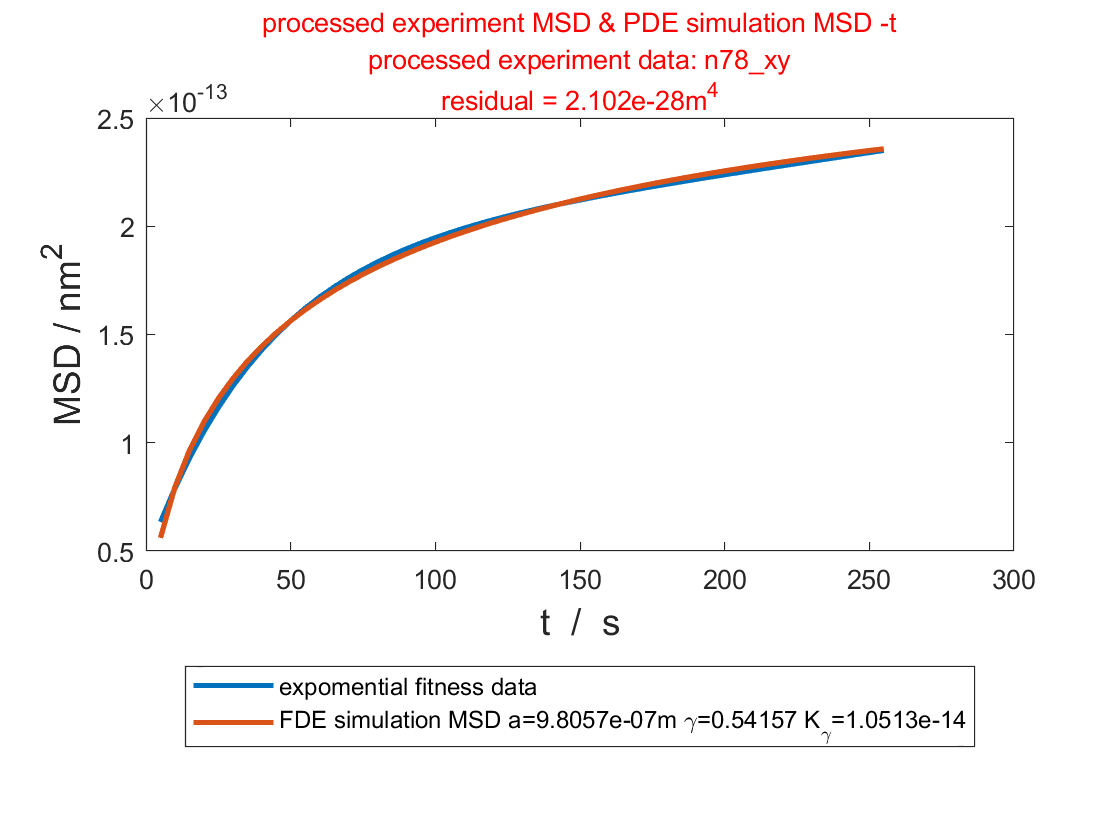

a=best_para(1);%m
Gamma=best_para(2);
K_gamma=best_para(3);


simulation_MSD=[];
for t=experiment_interval*[1:min_length]
    sum_number=10;
    sum_list=zeros(sum_number,1);
    for m=1:sum_number
        sum_list(m)=((-1)^m/m^2)*mlf(Gamma,1,-K_gamma*m^2*pi^2/a^2*t^Gamma,6);
    end
    simulation_MSD=[simulation_MSD,a^2*(1/3+4/pi^2*sum(sum_list))];
end
residual=sum((interceptive_experiment_MSD-simulation_MSD).^2);

figure
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2,'displayname','expomential fitness data')
hold on
legend_name=strcat('FDE simulation MSD',' a= ',num2str(a),'m \gamma=',num2str(Gamma),' K_\gamma= ',num2str(K_gamma));
plot(time_scale,simulation_MSD,"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / nm^2','FontSize',14);
title({['processed experiment MSD & PDE simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');